# **Lesson III.7:**   **The Singular Value Decomposition II**

**Geometry of the SVD.    **The SVD reveals that any linear maps from ${\mathbb R}^n$ to ${\mathbb R}^m$ can be thought of the composition of three linear maps where the first and last are isometries (length preserving) and the second stretches (or contracts) along the coordinate axes.     We examine these three maps graphically for several linear maps from ${\mathbb R}^2$ to ${\mathbb R}^2$ below.    For each real $2\times 2$ matrix $A=U\Sigma V^T$considered, there are two rows of four plots.   In the first row:

- The first plot, showing the columns of a matrix $F$, is intended to be the image of a face.   

- The second plot, showing the columns of $V^TF$, displays the action of $V^T$ on $F$.

- The third plot, showing the columns of $\Sigma V^T F$, displays the cumulative action of $V^T$ and $\Sigma$ on $F$.

- The fourth plot, showing the columns of $U\Sigma V^TF=AF$, display the cumulative action of $V^T,~\Sigma$ and $U$ on $F$.

In the second row:

- The first plot, showing the columns of a matrix $F$, is intended to be the image of a face.   

- The second plot, showing the columns of $V^TF$, displays the action of $V^T$ on $F$.

- The third plot, showing the columns of $\Sigma F$, displays the individual action of $\Sigma$ on $F$.

- The fourth plot, showing the columns of $U F$, display the individual action of $U$ on $F$.

face_svd([1 2; 0 1]) 
figure
face_svd([3 2; 2 -1])
figure
face_svd([1/2 1/2; 1/2 1])

A consequence of the SVD is that the image of the unit circle is always an ellipse having a major axis of length $2\sigma_1$ and a minor axis of length $2\sigma_2$.  And an important inequality relating the length of $A{\bf x}$ to ${\bf x}$ highlights the geometric meaning of $\sigma_1$:

        (III.7.1)                $||A{\bf x}||~\le~\sigma_1||{\bf x}||$.

**Polar decomposition.**  For square matrices there is a factorization, the ***polar decomposition***, that can be derived from the SVD and has a similar geometric interpretation.   Specifically, a square matrix$A$may be factored as $QS$ where $Q$ is orthogonal ($Q^TQ=I)$and $S$ is real symmetric ($S^T=S$) with nonnegative eigenvalues (positive semi-definite): 

        (III.7.2)        $A=U\Sigma V^T=UV^TV\Sigma V^T=QS\qquad\text{where}\quad Q=UV^T\quad\text{and}\quad S=V\Sigma V^T$

Geometrically, the action of $S$ is to stretch or contract in $n$ orthogonal directions (not generally aligned with the coordinate axes).   The action of $Q$, an orthogonal matrix, is an isometry (a rotation or reflection).   

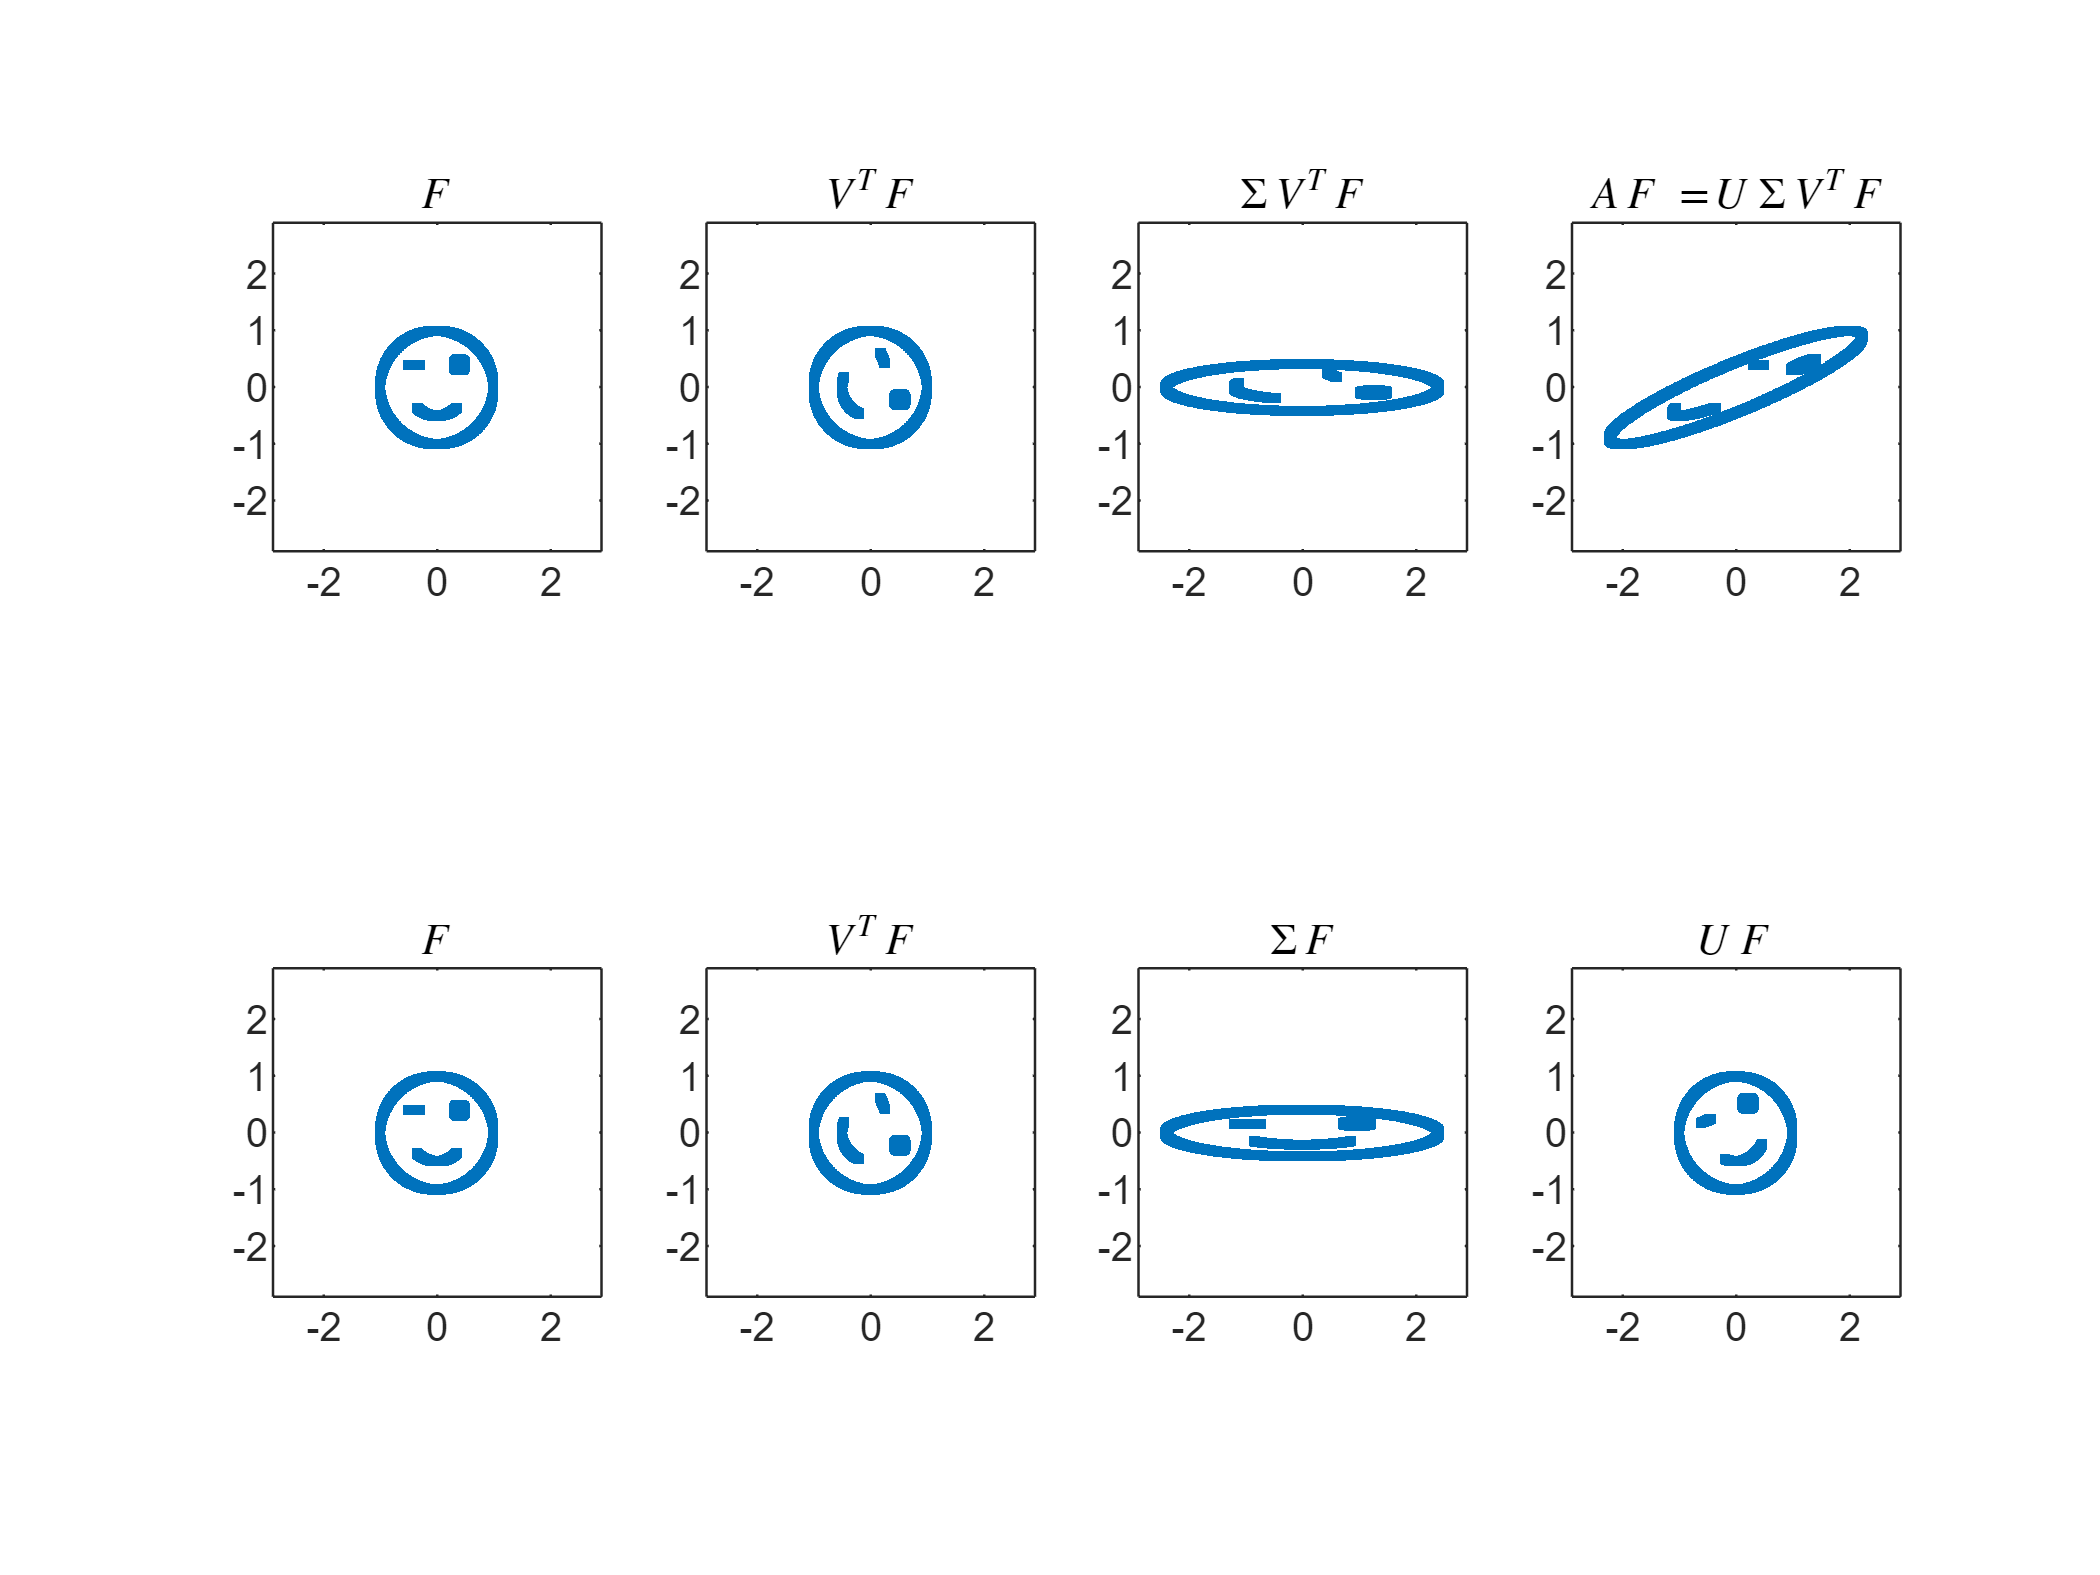

face_qs([1 2; 0 1]) 

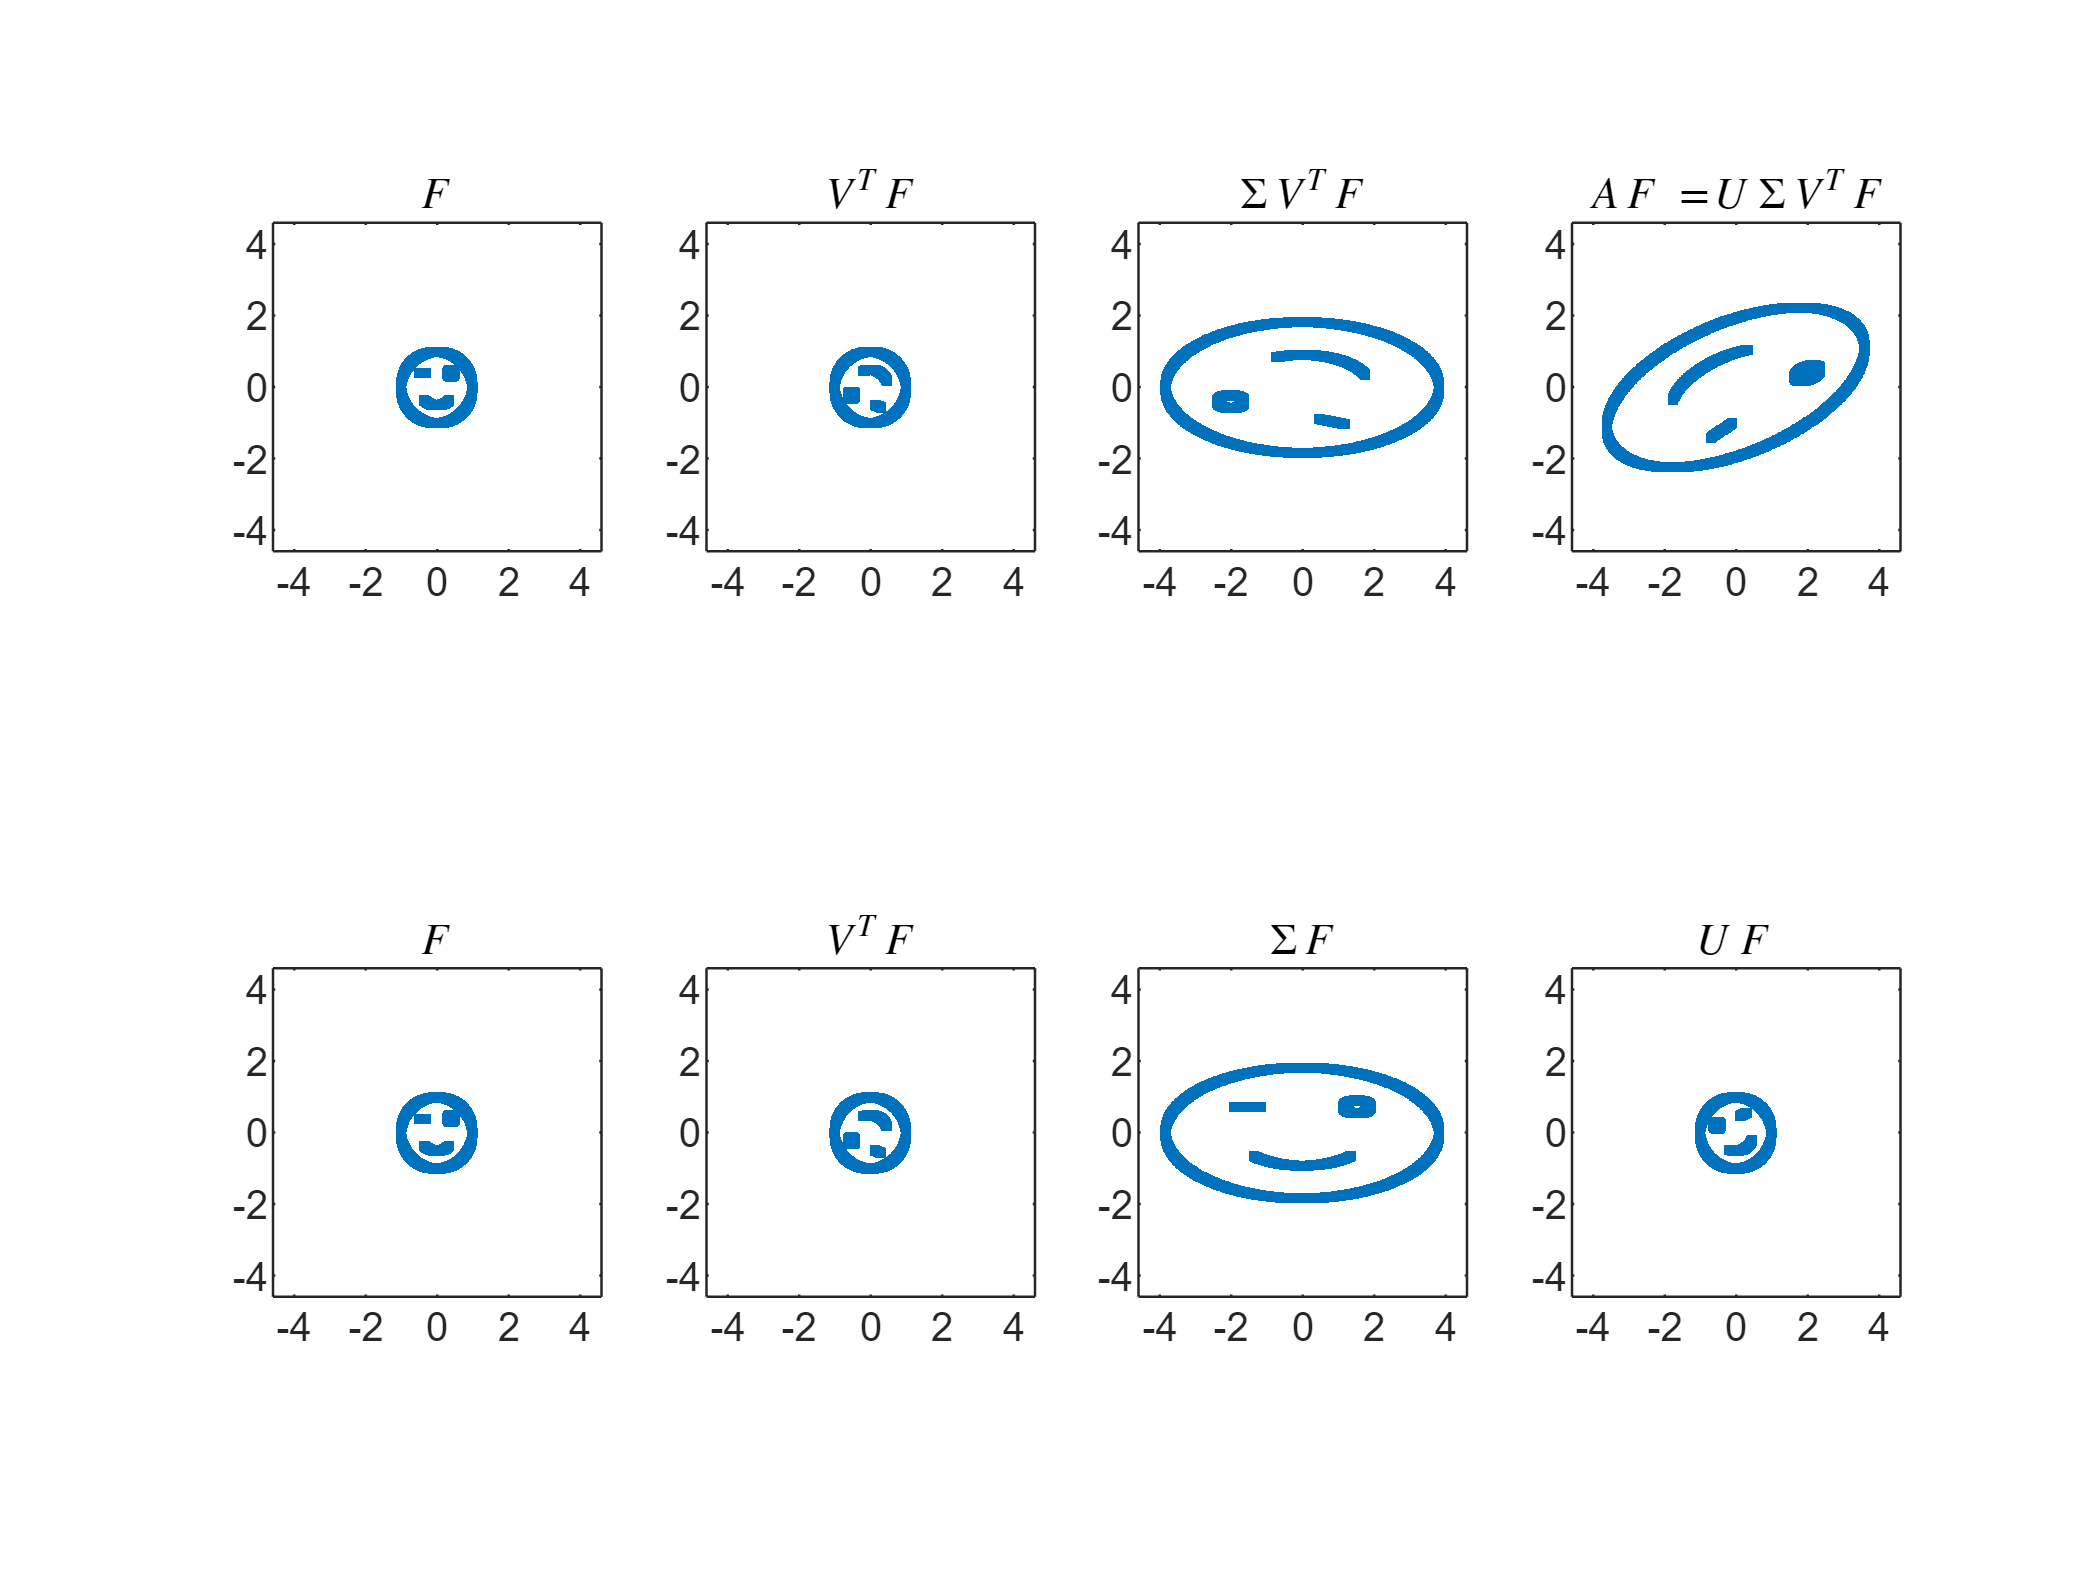

figure
face_qs([3 2; 2 -1])

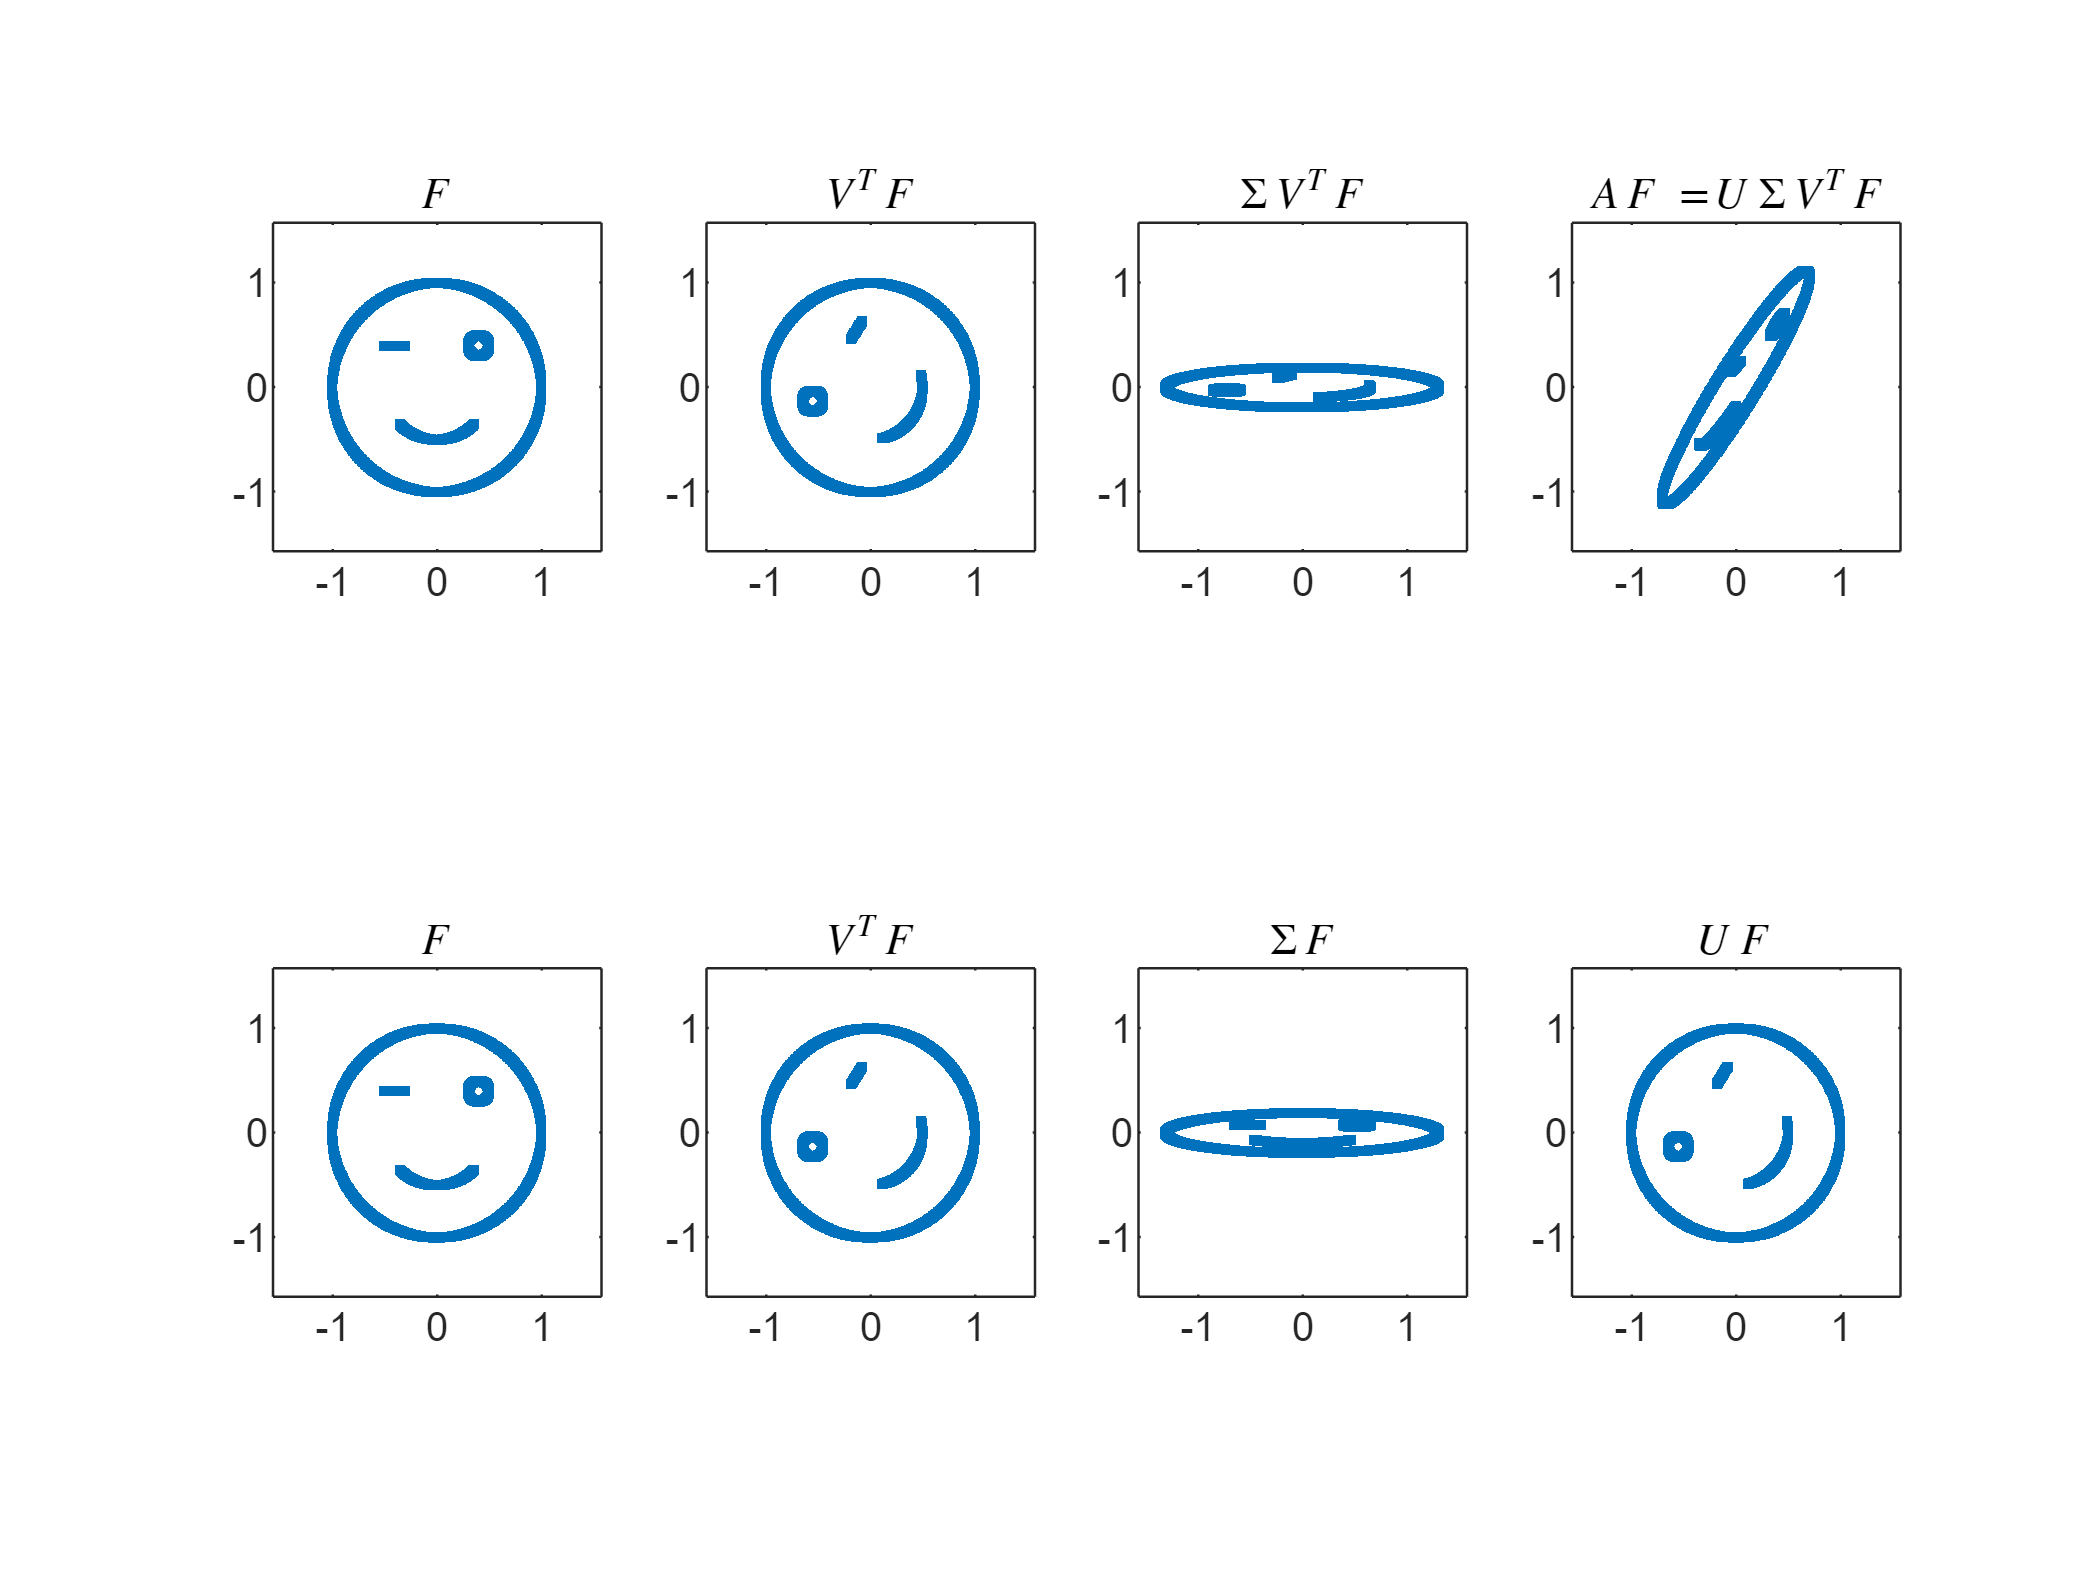

figure
face_qs([1/2 1/2; 1/2 1])

**Decomposition of the SVD as a linear combination of rank one maps. ** Applying the outer product expansion to the SVD gives an expansion of the matrix as a linear combination of $r$ rank 1 matrices:

        (III.7.3a)    $A=\left[\matrix{{\bf u}_1 & \cdots & {\bf u}_m}\right]
\left[\matrix{
\sigma_1 & & & & &  \cr 
& \ddots &&&&\cr
& & \sigma_r &&&\cr
& & & 0 && \cr
&&& &\ddots & \cr
&&&&&0
}\right]
\left[
\matrix{{\bf v}_1 & \cdots & {\bf v}_n}\right]^T$

        (III.7.3b)    $A=\left[\matrix{\sigma_1{\bf u}_1 & \cdots &\sigma_r {\bf u}_r&{\bf 0}&\cdots &{\bf 0}}\right]
\left[
\matrix{{\bf v}_1 & \cdots & {\bf v}_n}\right]^T$

        (III.7.3c)    $A=\sigma_1 {\bf u}_1 {\bf v}_1^T~+~\sigma_2{\bf u}_2{\bf v}_2^T+\cdots+\sigma_r{\bf u}_r{\bf v}_r^T$

**The compact SVD.  **From (III.7.3c) it is evident that only the first $r$ columns of $U$ and $V$ affect the final result of multiplying out the SVD.    Hence, we can alternatively factor $A$ with versions of $U$ and $V$ that only possess those columns:

        (III.7.4a)        $A= \tilde U \tilde \Sigma \tilde V^T$    

where    

        (III.7.4b)        $\tilde U=\left[\matrix{{\bf u}_1&\cdots&{\bf u}_r}\right]$,    $\tilde\Sigma=\left[\matrix{\sigma_1& & \cr & \ddots & \cr & & \sigma_r}\right]$    and     $\tilde V=\left[\matrix{{\bf v}_1&\cdots&{\bf v}_r}\right]$.

Note that $\tilde U$ is $m\times r$ with orthonormal columns, $\tilde \Sigma$ is $r\times r$ (invertible) and $\tilde V$ is $n\times r$ with orthonormal columns.   This factorization is known as the ***compact SVD***.    The compact SVD may be considered a significant refinement of the CR factorization.

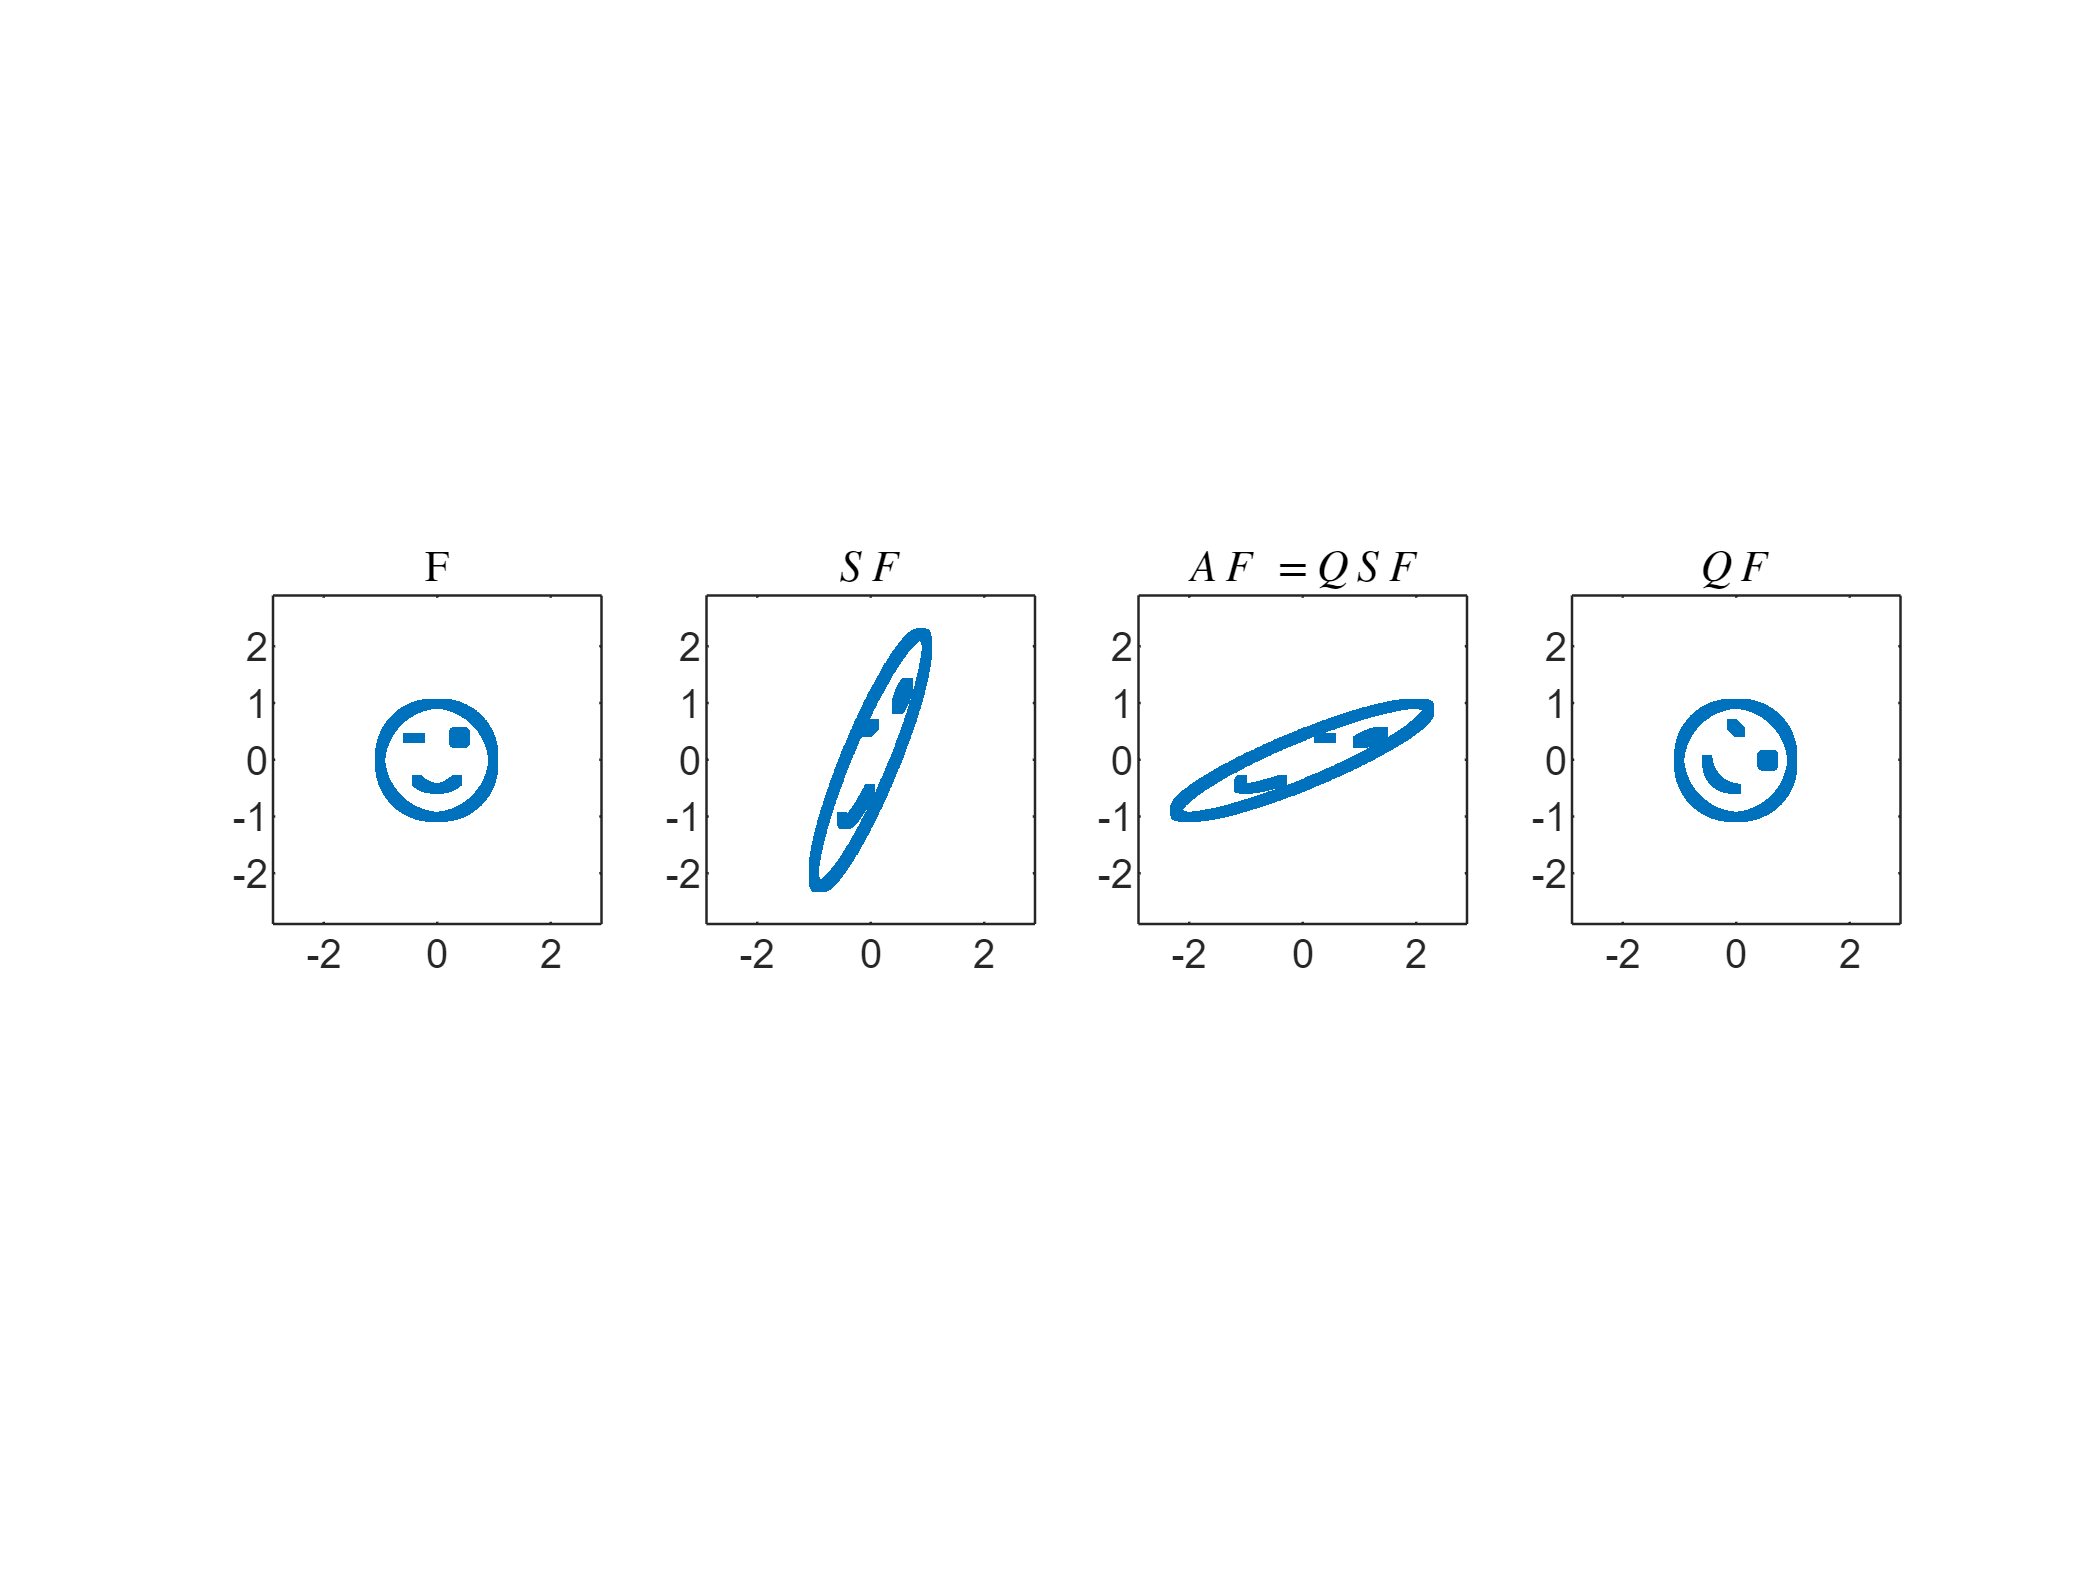

A=[1 2 3; 4 5 6; 7 8 9]
[U,Sigma,V]=svd(A)
r=rank(A)
tU=U(:,1:r)
tSigma=Sigma(1:r,1:r)
tV=V(:,1:r)
tU*tSigma*tV'

**The SVD and the four fundamental subspaces.**

- An orthonormal basis for $\text{col}(A)$ is the first $r$ columns of $U$: $\{{\bf u}_1,\cdots,{\bf u}_r\}$.

- An orthonormal basis for $\text{nul}(A^T)$ is remaining columns of $U$: $\{{\bf u}_{r+1},\cdots,{\bf u}_m\}$.

- An orthonormal basis for $\text{row}(A)$ is the first $r$ columns of $V$:  $\{ {\bf v}_1,\cdots,{\bf v}_r\}$.

- An orthonormal basis for $\text{nul}(A)$ is the remaining columns of $V$:  $\{{\bf v}_{r+1},\cdots,{\bf v}_n\}$.

**The pseudoinverse (the joys of left inverses).  **The pseudoinverse extends the idea of least-squares solutions by selection of the unique least-squares solution in the row space of the coefficient matrix.  Moreover, we determine a $n\times m$ matrix $A^+$, the ***pseudo inverse*** of $A$, that produces this unique least-square solution in the row space by multiplication against the RHS:  ${\bf x}=A^+{\bf b}$.  Consider an $m\times n$ matrix $A$ and the linear system $A{\bf x}={\bf b}$ where ${\bf b}\in{\mathbb R}^m$.   Of course, there may be no solution for this system, and if there is a solution there may be more than one.     That is, this equation does not by itself define a unique vector ${\bf x}$.    We modify the mathematical conditions expressed in$A{\bf x}={\bf b}$ in two ways, each involving an orthogonal projection, to obtain ${\bf x}$, the unique least-squares solution in the row space.    From the compact SVD of $A=\tilde U \tilde\Sigma \tilde V^T$, we have two orthogonal projections $P_c=\tilde U \tilde U^T$ projecting into $\text{col}(A)$ and $P_r=\tilde V \tilde V^T$projecting into $\text{row}(A)$.   We also note  $\tilde U^T\tilde U=\tilde V^T\tilde V=I$, the $r\times r$ identity matrix.

figIII7a()

The first modification is to seek solutions in the least-squares sense; that is, ${\bf b}$ is replaced by it projection into the column space $\tilde{\bf b}=\tilde U \tilde U^T{\bf b}$.   The modified equation $A{\bf x}=\tilde {\bf b}$ does have solutions, but this solution may not be unique; that is, the modified equation still does not define a specific vector ${\bf x}$.   To define a specific least-squares solution ${\bf x}$, we modify the problem with the requirement that ${\bf x}\in\text{row}(A)$.   Hence, if ${\bf \xi}$ is a least-squares solution, we have ${\bf x}=\tilde V \tilde V^T{\bf \xi}$.  

To begin the derivation, we rewrite the equation $A{\bf \xi}=\tilde{\bf b}$ in terms of the SVD for $A$:

        (III.7.5a)        $\tilde U\tilde \Sigma \tilde V^T{\bf \xi}=\tilde U \tilde U^T{\bf b}$.

Multiplying on the left by $U^T$ yields

        (III.7.5b)        $\tilde \Sigma \tilde V^T{\bf \xi}=\tilde U^T{\bf b}$.

Multiplying on the left by $\tilde \Sigma^{-1}$ gives

        (III.7.5c)        $\tilde V^T{\bf \xi}=\tilde\Sigma^{-1}\tilde U^T{\bf b}$.

Multiplying on the left by $\tilde V$ gives

        (III.7.5d)    ${\bf x}=A^+{\bf b}$    where    $A^+=\tilde V \tilde \Sigma^{-1} \tilde U^T$.

MATLAB provides a function `pinv(A)` that computes the pseudo inverse:

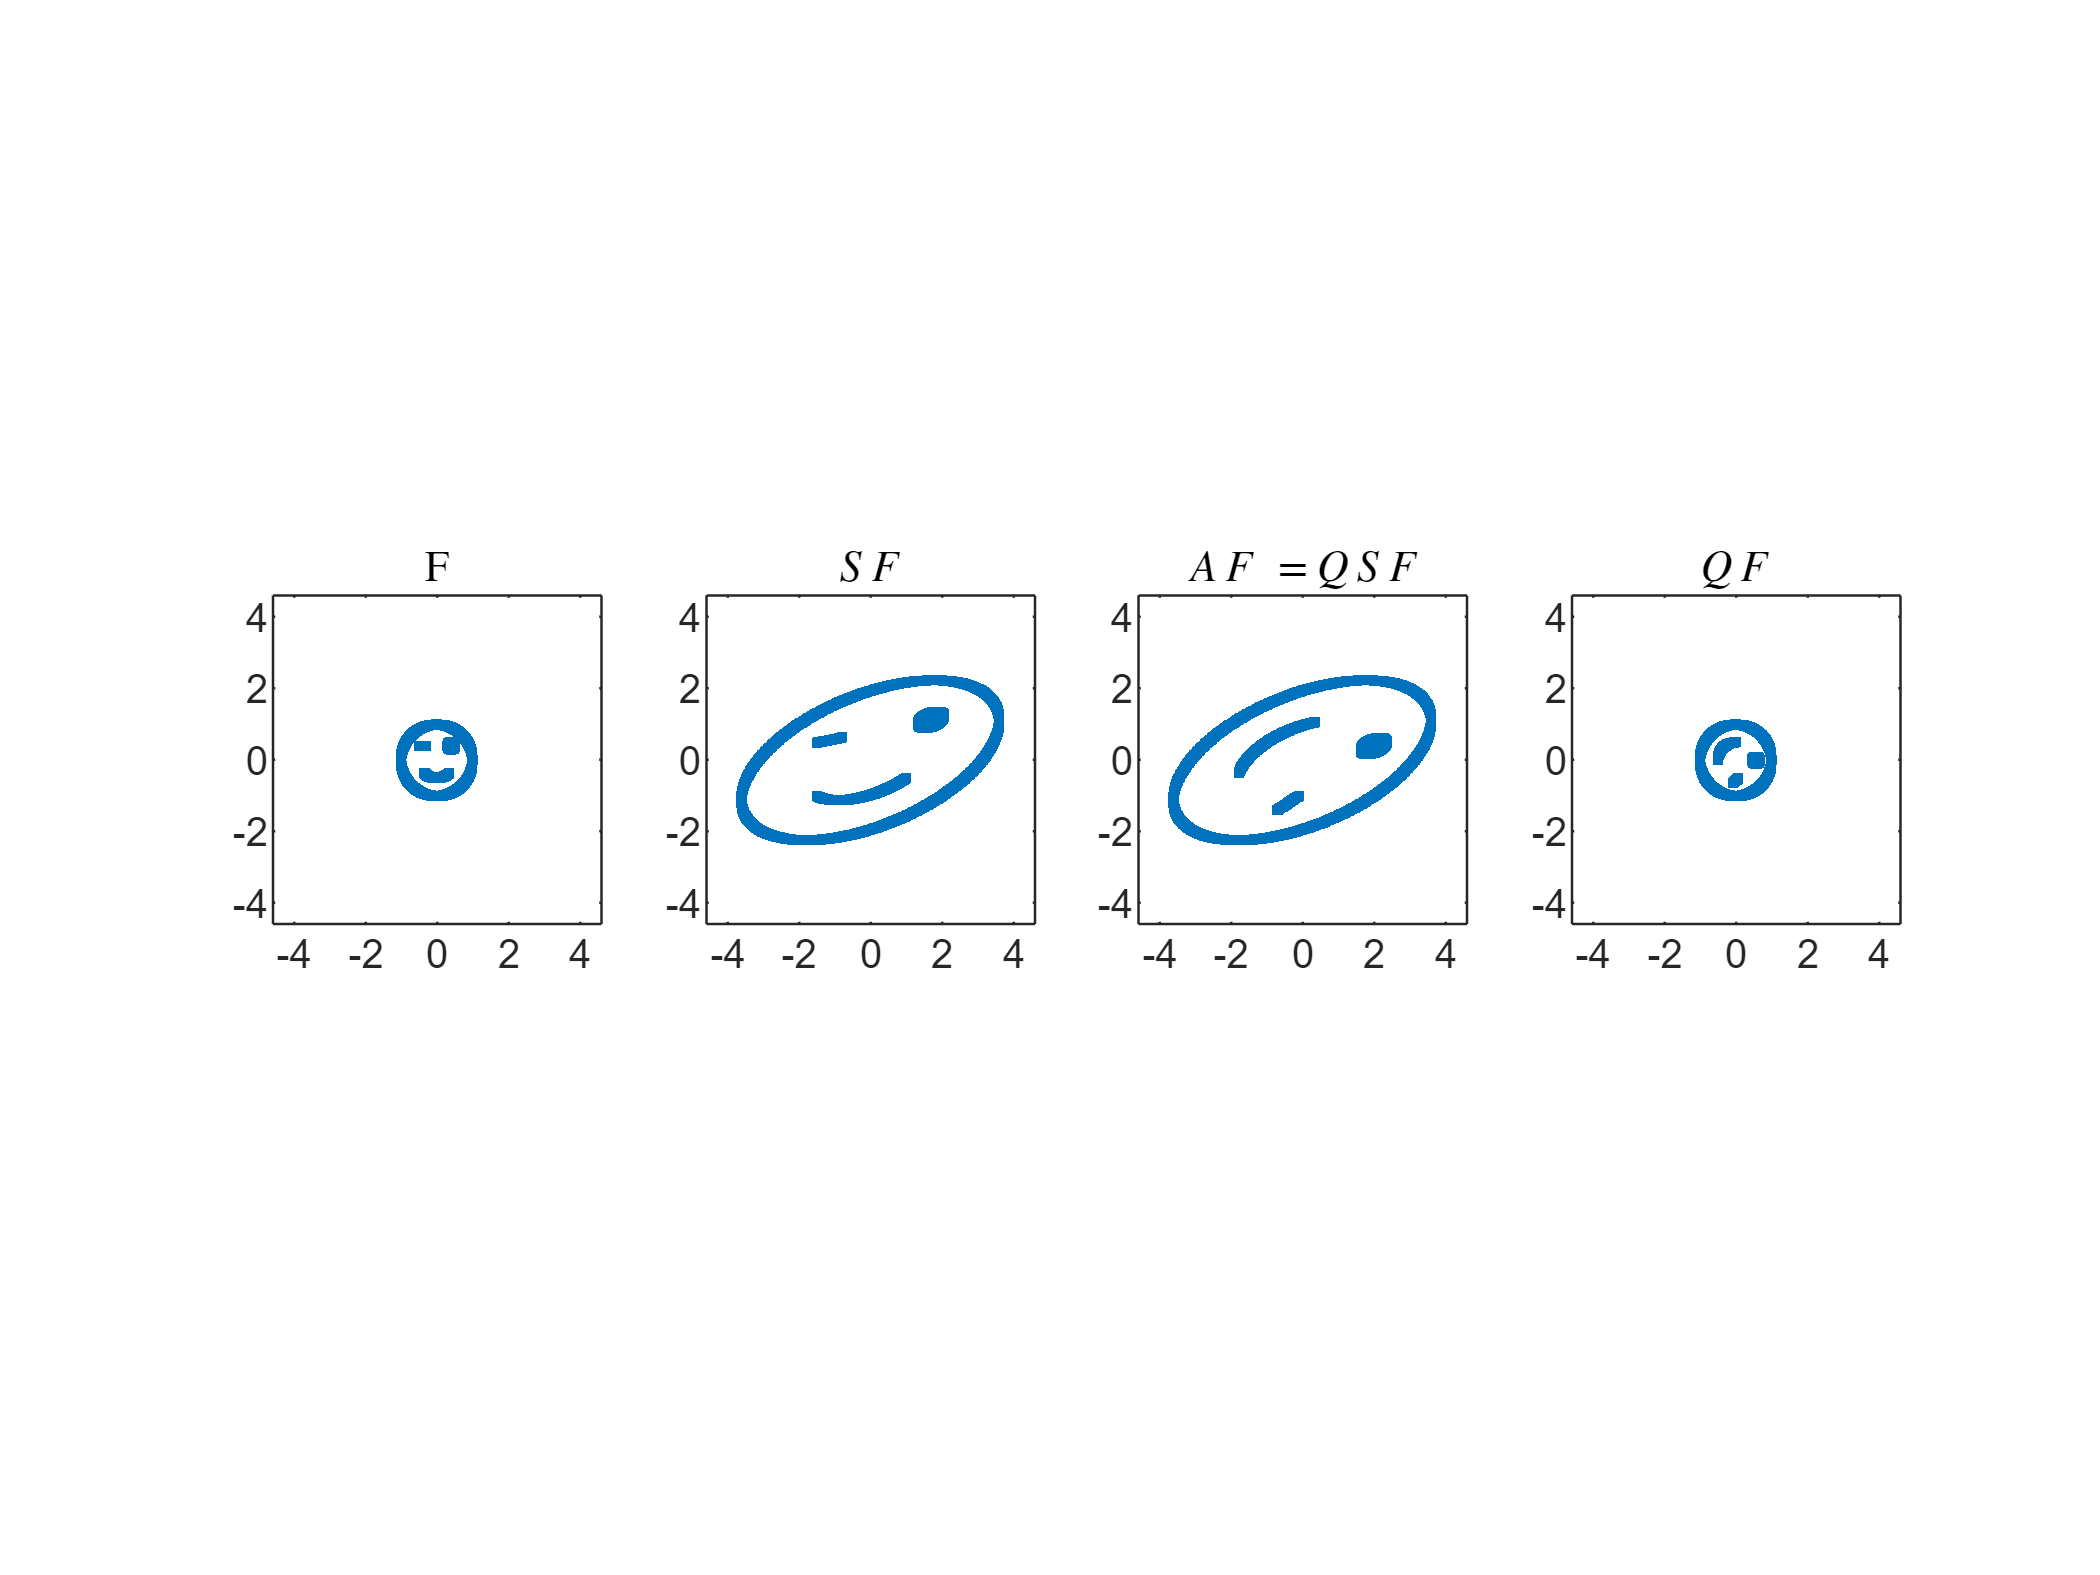

A=[1 2 3; 4 5 6; 7 8 9]

Apinv=pinv(A)

Of course, if $A$ is invertible, the pseudoinverse equals, except for round-off errors, the inverse.

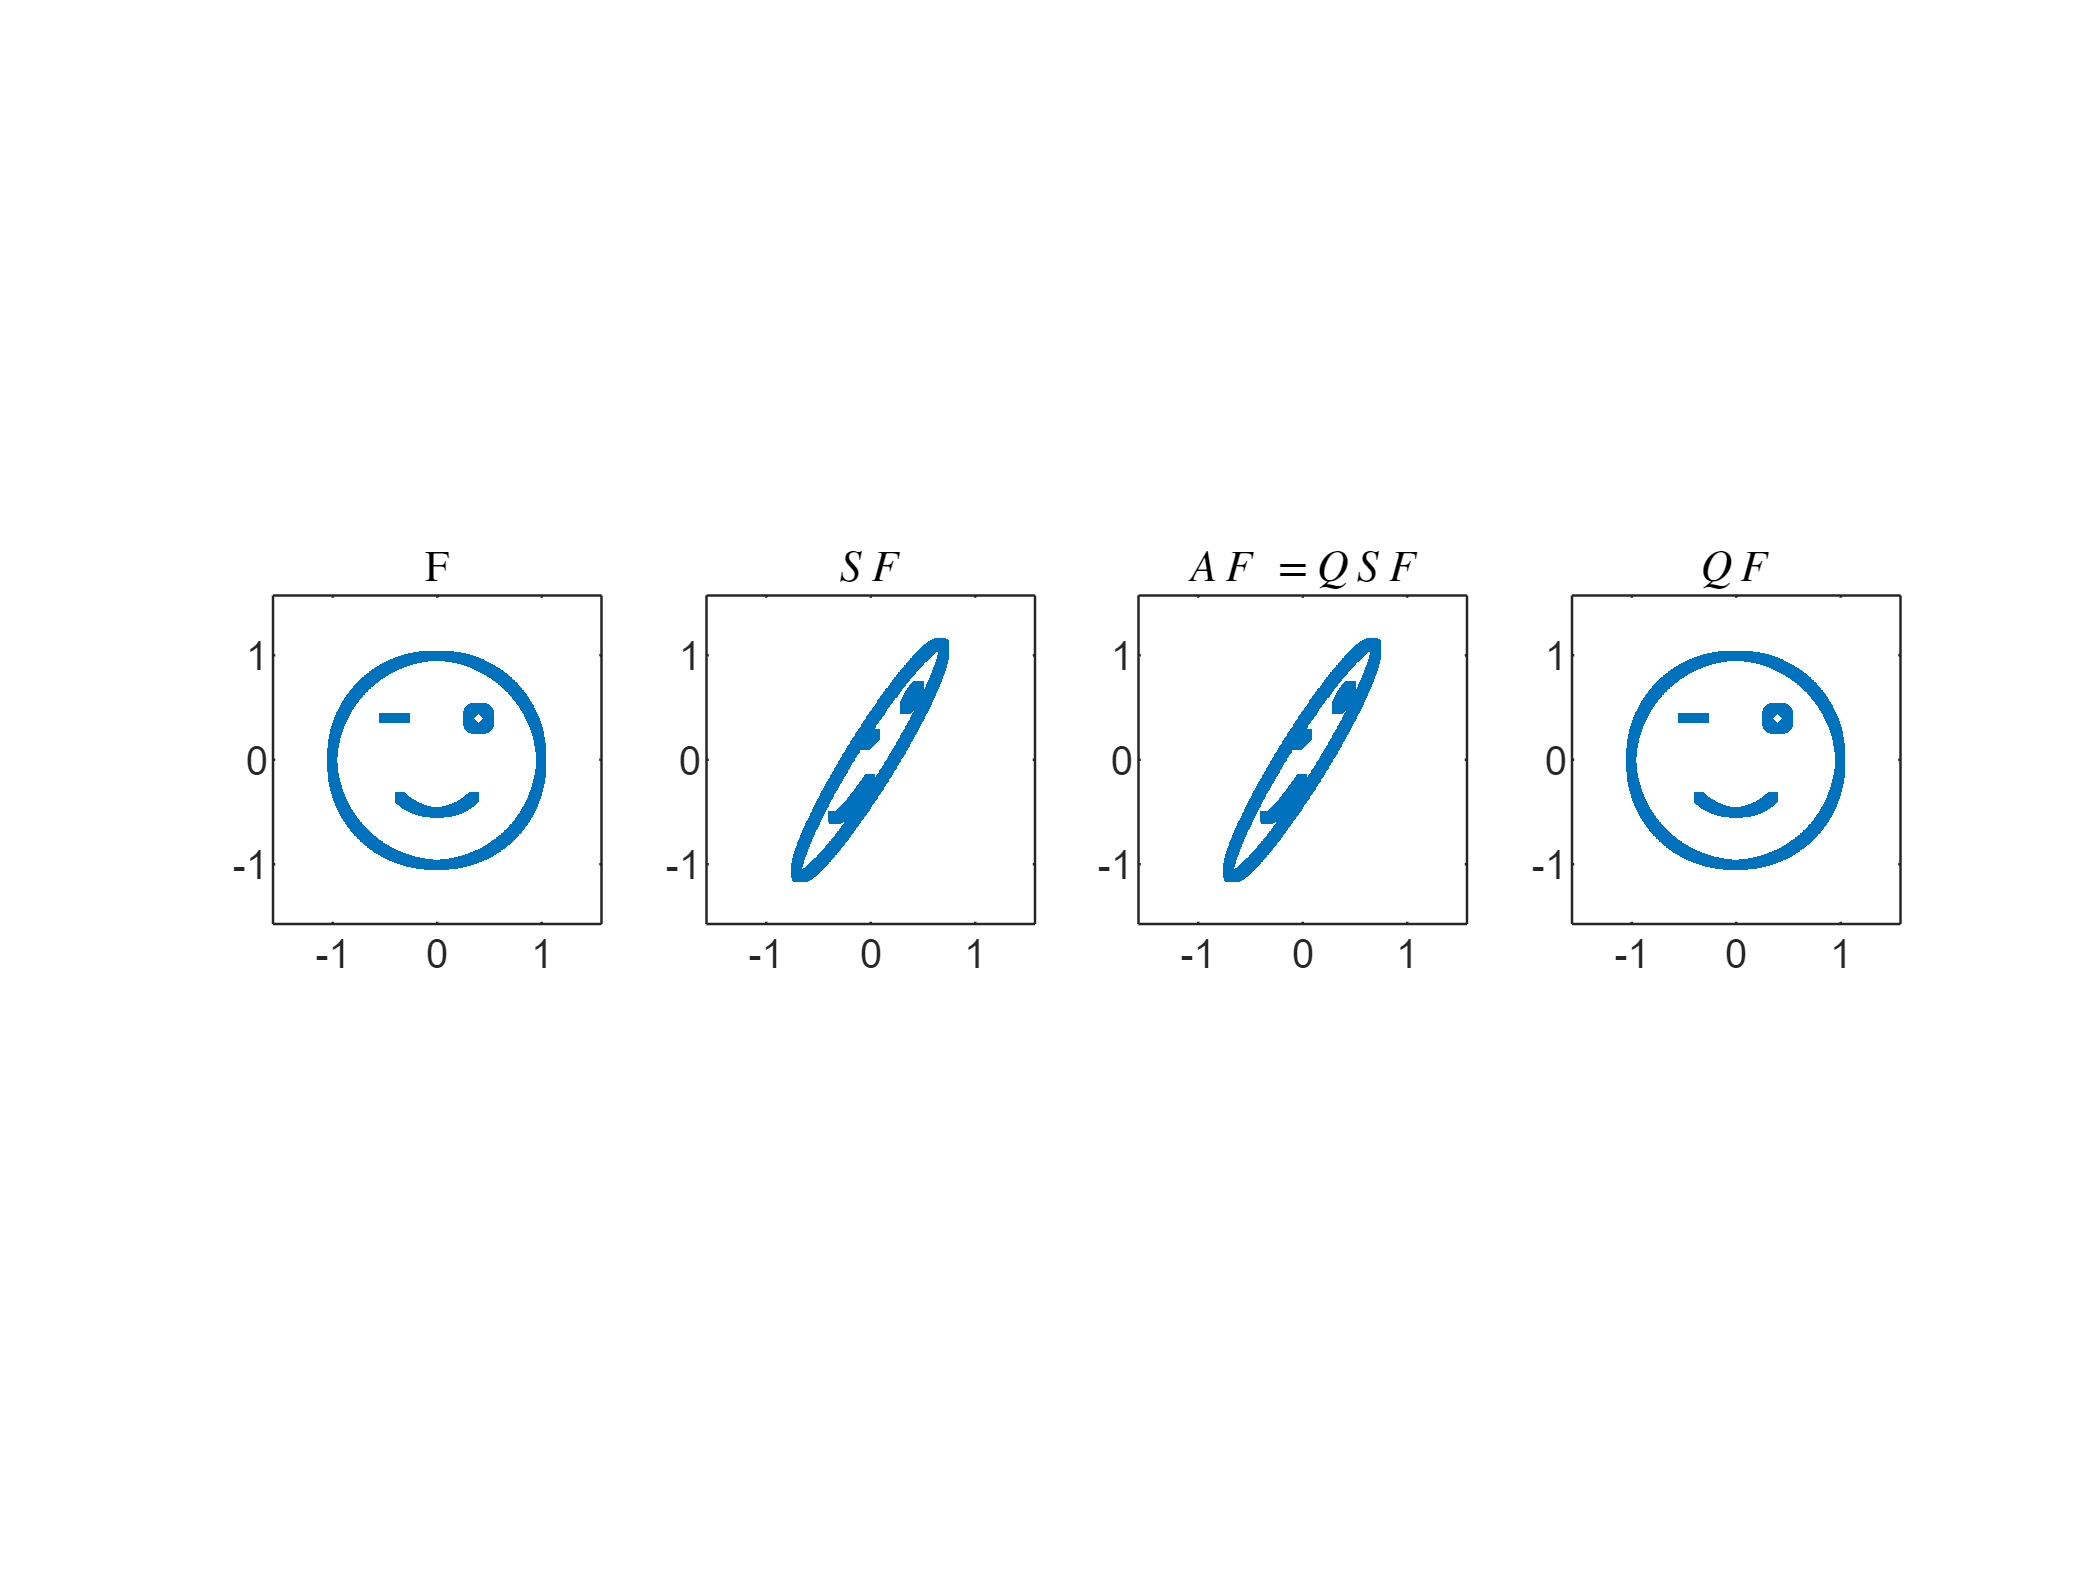

pinv([2 1 0; 1 2 1; 0 1 2])-inv([2 1 0; 1 2 1; 0 1 2])

**Image compression.   **Despite the heading of this section, the topic is compressing the amount of storage needed for a matrix, but we note that an image can be thought of as a matrix of pixels.    To store an $m\times n$ matrix generally requires storing $mn$numbers.    However, if we represent the matrix in the format of (III.7.3c), then we need to store the $r$ singular values, the $rm$ values  of the components of the vectors $\{{\bf u}_1,\dots,{\bf u}_r\}$ and the $rn$ values of the components of the vectors $\{{\bf v}_1,\dots,{\bf v}_r\}$ which is a total of $r+rm+rn=r(1+m+n)$ numbers.   If $r$ is relatively small compared with $m$ and $n$ this may represent a substantial saving in storage.   For example, if $m=n=1000$ and $r=100$ then the storage requirements using (III.7.3c) are only $100(1+1000+1000)=200,100$ numbers rather than the $1000\times 1000=1,000,000$ entries of the matrix.   Furthermore, if many of the singular values of the matrix are relatively small compared with those at the beginning of the list, ignoring those smaller singular values may still produce a reasonably accurate representation of the matrix with considerable savings in storage.  A demonstration of SVD-based matrix compression applied to images can be found at [https://timbaumann.info/svd-image-compression-demo/](https://timbaumann.info/svd-image-compression-demo/)

**The complex SVD.   **The SVD for complex matrices are but a tiny tweak of the SVD for real matrices.  The major change is that the orthogonal matrices $U$ and $V$ become ***unitary ***matrices meaning that

            
$$U^HU=UU^H=I\qquad\text{and}\qquad
V^HV=VV^H=I.$$


Of course the arithmetic become complex (why else would they be called complex numbers?).   

A=sym([2 3+i 2i; 4 i 2])
    [S,D]=eig(A'*A)

We can see that the arithmetic has become hopelessly complex.    This of course is one of the reasons the electronic computer was invented.     We find (or let MATLAB find) an orthonormal eigenbasis.

[V,~]=qr(S)

Be aware that MATLAB is using $\sigma_\ell$ for values other than the singular values.   

We now need to deal with the order of the eigenvalues.   We make use of an exchange matrix to switch the first and last eigenvalues:

P=sym([0 0 1; 0 1 0; 1 0 0])
V=P*simplify(V)
Sigma=P*D*P
U=inv(Sigma(1:2,1:2))*A*V

It is notable that if one is willing to give up the exact algebraic answer and accept a double percision approximation much of the fuss goes away (or at least hidden within MATLAB's inner workings):

[nU, nSigma, nV]=svd([2 3+i 2i; 4 i 2])
nU*nSigma*nV'

**Follow-up Problems****:**

**Problem III.7.1:   **Show that there is always a nonzero vector ${\bf v}$ such that $||A{\bf v}||=\sigma_1||{\bf v}||$.

**Problem III.7.2:   **For a nonsingular $n\times n$ matrix $A$ explain why  $\sigma_n||{\bf x}||\le||A{\bf x}||\le\sigma_1||{\bf x}||$.

**Problem III.7.3:   **Find the polar decomposition of $A=\left[\matrix{1 & 2\cr 1 & -1\cr 1& -1}\right]$.

**Problem III.7.4:    **Show that the formula for the pseudo inverse can be derived by forming the normal equations and replacing $A$ by its compact SVD.

**Problem III.7.5:  **Find the pseudo inverse of $A=\left[\matrix{1 & 2\cr 1 & -1\cr 1& -1}\right]$.

**Problem III.7.6:  **Find the compact SVD of $A=\left[\matrix{1 & 2\cr 1 & -1\cr 1& -1}\right]$.

**Problem III.7.7:   (MATLAB problem) **Consider the matrix

A=[1 1 1 1 1; 1 2 2 2 1; 1 2 3 2 1; 1 2 2 2 1; 1 1 1 1 1];
singularvalues=svd(A)

How well can $A$ be approximated by a rank 1 matrix?   a rank 2 matrix?

**Problem III.7.8:**  Find an SVD of the complex matrix $A=\left[\matrix{1& i\cr i& 1}\right]$.

function face_svd(A)
[U,Sigma,V]=svd(A);

r = 2

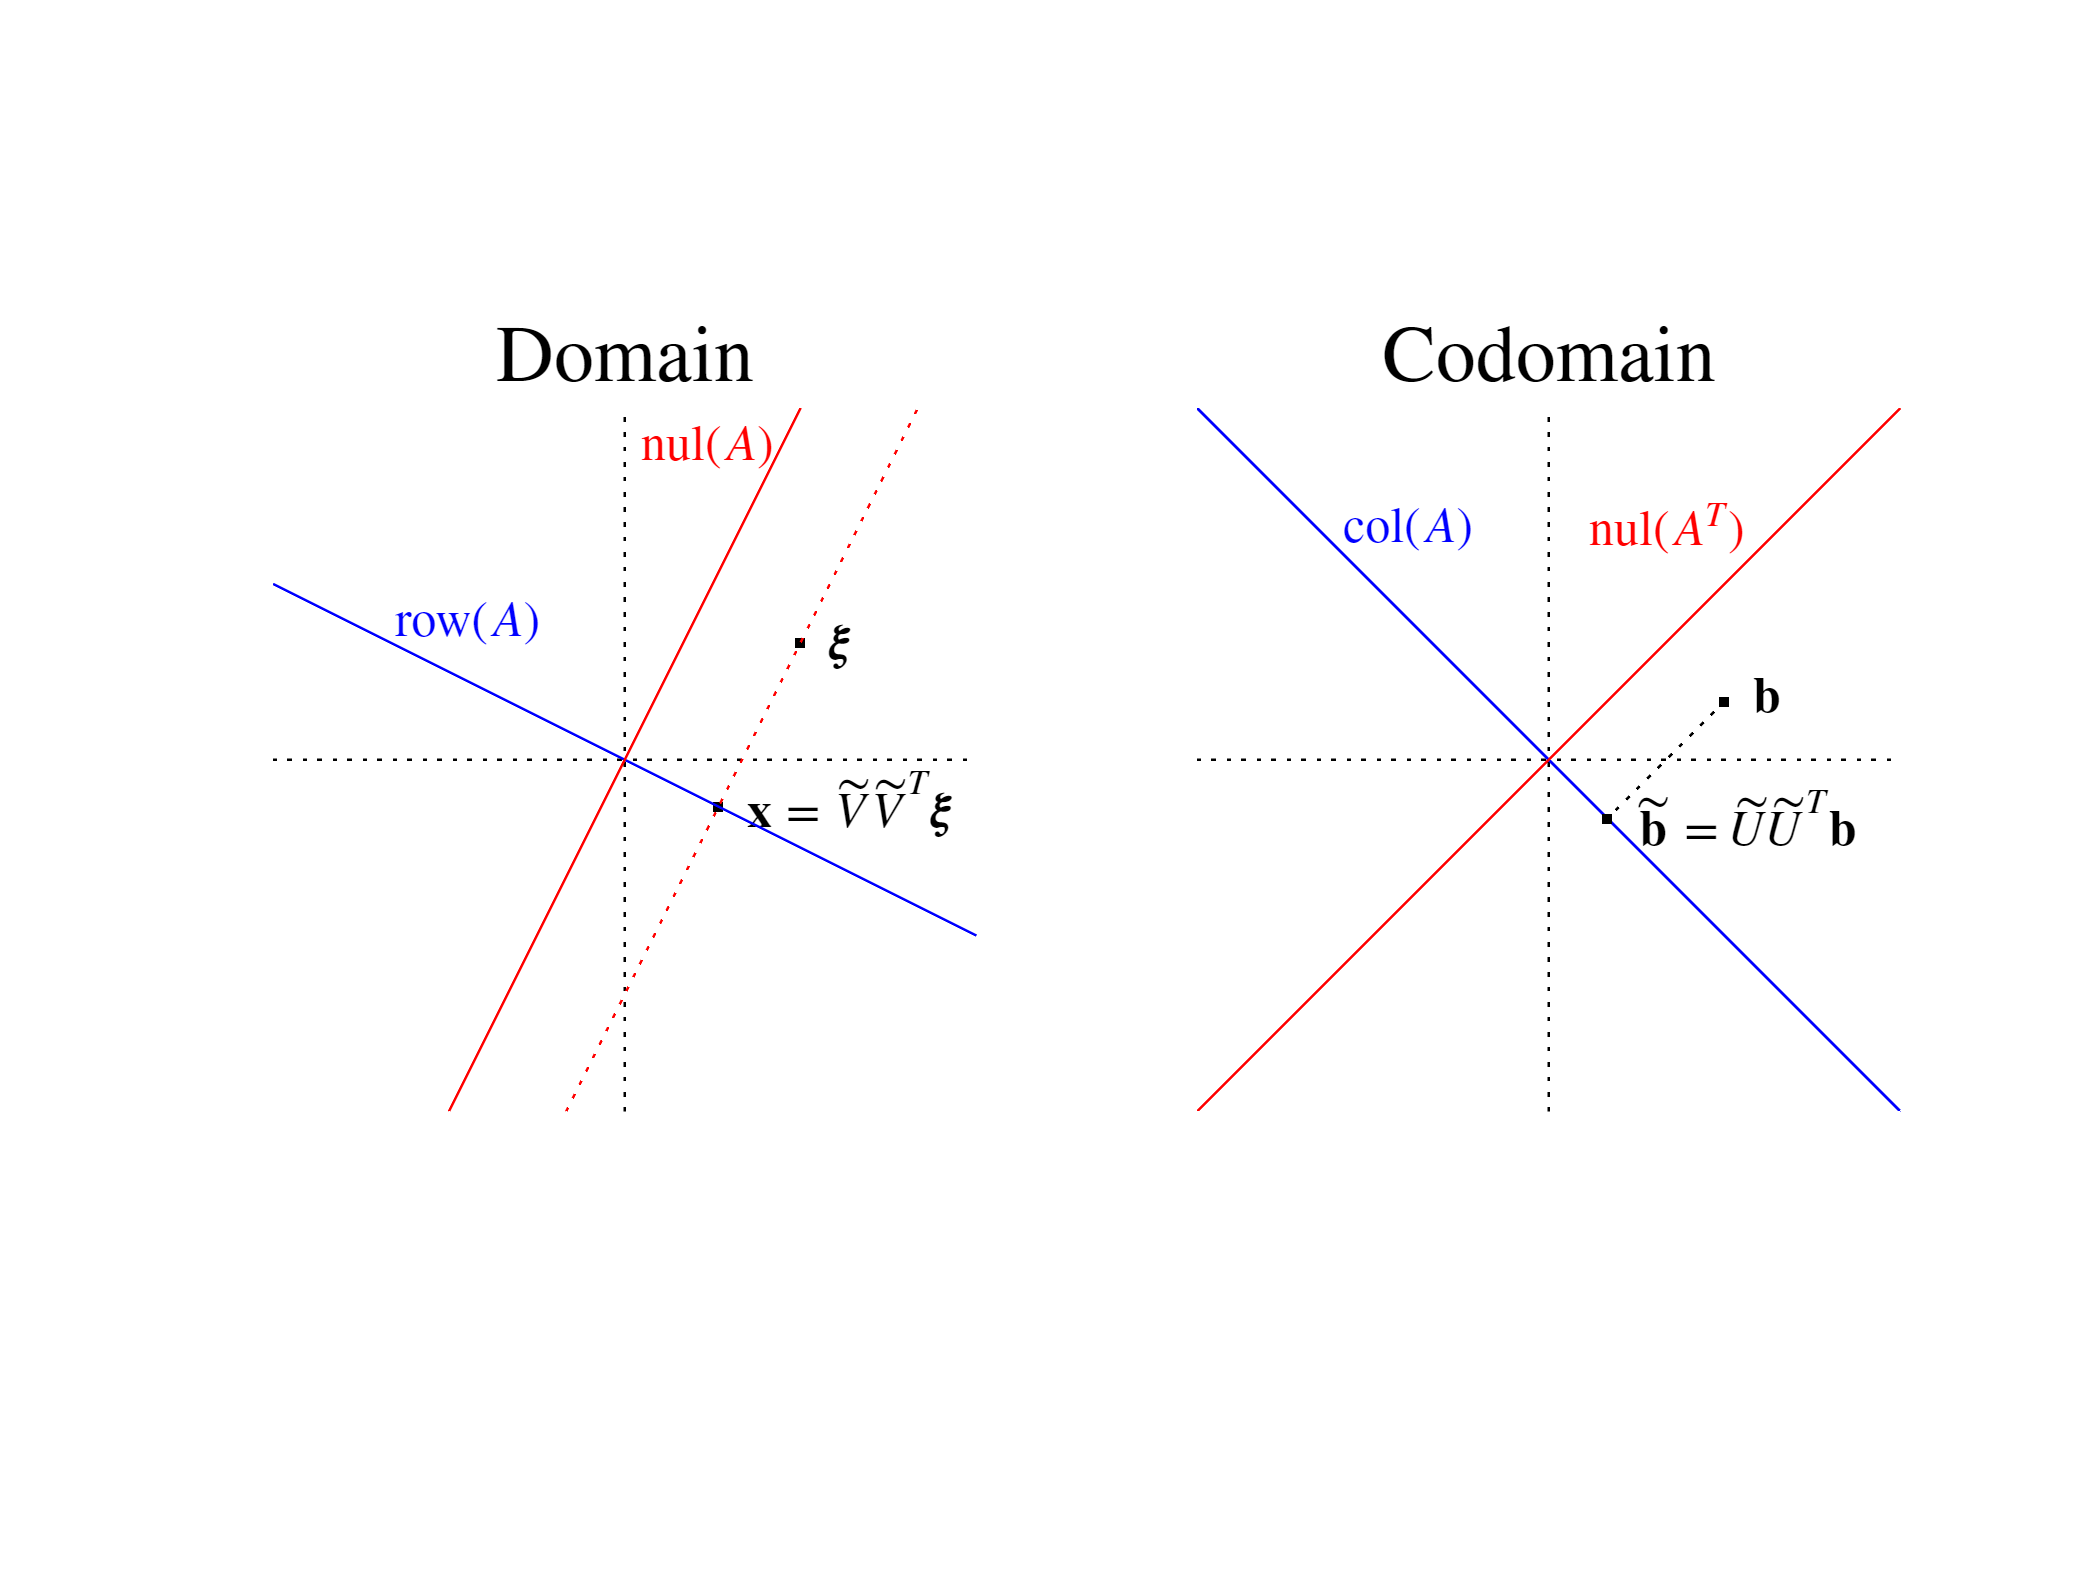

face1=make_face();
face2=V'*face1;
face3=Sigma*face2;
face4=U*face3;
s=max(1,Sigma(1,1));   % illustrates role of first sigular value for scaling
subplot(2,4,1)
    plot_face(face1,s)
    title('$F$','interpreter','latex')

subplot(2,4,2)
    plot_face(face2,s)
    title('$V^T\,F$','interpreter','latex')
subplot(2,4,3)
    plot_face(face3,s)
    title('$\Sigma \, V^T\,F$','interpreter','latex')
subplot(2,4,4)
    plot_face(face4,s)
    title('$A\,F~=~U\,\Sigma \, V^T\,F$','interpreter','latex')
subplot(2,4,5)
    plot_face(face1,s)
    title('$F$','interpreter','latex')
subplot(2,4,6)
    plot_face(face2,s)
    title('$V^T\,F$','interpreter','latex')
subplot(2,4,7)
    plot_face(Sigma*face1,s)
    title('$\Sigma \,F$','interpreter','latex')
subplot(2,4,8)
    plot_face(U*face1,s)
    title('$U\,F$','interpreter','latex')

$$A = \left(\begin{array}{ccc} 2 & 3+\mathrm{i} & 2\,\mathrm{i}\\ 4 & \mathrm{i} & 2 \end{array}\right)$$

end

$$S = \left(\begin{array}{ccc} -\frac{25}{37}-\frac{2}{37}\,\mathrm{i} & \frac{103}{111}+\sqrt{337}\,\left(-\frac{4}{111}-\frac{11}{222}\,\mathrm{i}\right)+\frac{89}{222}\,\mathrm{i} & \sqrt{337}\,\left(\frac{4}{111}+\frac{11}{222}\,\mathrm{i}\right)+\frac{103}{111}+\frac{89}{222}\,\mathrm{i}\\ \frac{8}{37}-\frac{26}{37}\,\mathrm{i} & \frac{65}{444}+\sqrt{337}\,\left(-\frac{23}{444}+\frac{5}{222}\,\mathrm{i}\right)+\frac{121}{222}\,\mathrm{i} & \sqrt{337}\,\left(\frac{23}{444}-\frac{5}{222}\,\mathrm{i}\right)+\frac{65}{444}+\frac{121}{222}\,\mathrm{i}\\ 1 & 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & \frac{39}{2}-\frac{\sqrt{337}}{2} & 0\\ 0 & 0 & \frac{\sqrt{337}}{2}+\frac{39}{2} \end{array}\right)$$



function face_qs(A)

$$V = \begin{array}{l} \left(\begin{array}{ccc} \sqrt{2}\,\left(-\frac{25}{74}-\frac{1}{37}\,\mathrm{i}\right) & -\frac{\sigma_{2}-\frac{103}{111}-\frac{89}{222}\,\mathrm{i}}{\sigma_{3}} & \frac{\sigma_{2}+\frac{103}{111}+\frac{89}{222}\,\mathrm{i}}{\sigma_{4}}\\ \sqrt{2}\,\left(\frac{4}{37}-\frac{13}{37}\,\mathrm{i}\right) & -\frac{\sigma_{1}-\frac{65}{444}-\frac{121}{222}\,\mathrm{i}}{\sigma_{3}} & \frac{\sigma_{1}+\frac{65}{444}+\frac{121}{222}\,\mathrm{i}}{\sigma_{4}}\\ \frac{\sqrt{2}}{2} & \frac{1}{\sigma_{3}} & \frac{1}{\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{337}\,\left(\frac{23}{444}-\frac{5}{222}\,\mathrm{i}\right)\\ \sigma_{2}=\sqrt{337}\,\left(\frac{4}{111}+\frac{11}{222}\,\mathrm{i}\right)\\ \sigma_{3}=\sqrt{\frac{337}{72}-\sigma_{5}}\\ \sigma_{4}=\sqrt{\sigma_{5}+\frac{337}{72}}\\ \sigma_{5}=\frac{7\,\sqrt{337}}{72} \end{array}$$

[U,Sigma,V]=svd(A);
Q=U*V';
S=V*Sigma*V';
face=make_face();

$$P = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 1 & 0\\ 1 & 0 & 0 \end{array}\right)$$

face1=S*face;

$$V = \begin{array}{l} \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{1}{\sqrt{\frac{337}{72}-\sigma_{5}}} & \frac{1}{\sqrt{\sigma_{5}+\frac{337}{72}}}\\ \sqrt{2}\,\left(\frac{4}{37}-\frac{13}{37}\,\mathrm{i}\right) & \frac{\sigma_{4}\,\left(\sigma_{1}-7751+3370\,\mathrm{i}\right)}{299256} & \frac{\sigma_{3}\,\left(\sigma_{1}+7751-3370\,\mathrm{i}\right)}{299256}\\ \sqrt{2}\,\left(-\frac{25}{74}-\frac{1}{37}\,\mathrm{i}\right) & \frac{\sigma_{4}\,\left(\sigma_{2}-2696-3707\,\mathrm{i}\right)}{149628} & \frac{\sigma_{3}\,\left(\sigma_{2}+2696+3707\,\mathrm{i}\right)}{149628} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{337}\,\left(65+242\,\mathrm{i}\right)\\ \sigma_{2}=\sqrt{337}\,\left(206+89\,\mathrm{i}\right)\\ \sigma_{3}=\sqrt{337-7\,\sqrt{337}}\\ \sigma_{4}=\sqrt{7\,\sqrt{337}+337}\\ \sigma_{5}=\frac{7\,\sqrt{337}}{72} \end{array}$$

face2=Q*S*face;

$$Sigma = \left(\begin{array}{ccc} \frac{\sqrt{337}}{2}+\frac{39}{2} & 0 & 0\\ 0 & \frac{39}{2}-\frac{\sqrt{337}}{2} & 0\\ 0 & 0 & 0 \end{array}\right)$$

face3=Q*face;

$$U = \begin{array}{l} \left(\begin{array}{ccc} \frac{\sqrt{2}\,\left(\frac{128}{37}-\frac{120}{37}\,\mathrm{i}\right)}{\sqrt{337}+39} & \frac{4}{\sigma_{11}\,\left(\sqrt{337}+39\right)}+\frac{\sigma_{2}\,\sigma_{9}\,\mathrm{i}}{\sigma_{6}}+\frac{\sigma_{2}\,\sigma_{7}\,\sigma_{3}}{\sqrt{337}+39} & \frac{4}{\sigma_{12}\,\left(\sqrt{337}+39\right)}+\frac{\sigma_{1}\,\sigma_{10}\,\mathrm{i}}{\sigma_{6}}+\frac{\sigma_{1}\,\sigma_{8}\,\sigma_{3}}{\sqrt{337}+39}\\ \frac{\sqrt{2}\,\left(-\frac{124}{37}-\frac{4}{37}\,\mathrm{i}\right)}{\sqrt{337}-39} & -\frac{8}{\sigma_{11}\,\left(\sqrt{337}-39\right)}-\frac{\sigma_{2}\,\sigma_{9}}{\sigma_{5}}-\frac{\sigma_{2}\,\sigma_{7}\,\mathrm{i}}{\sigma_{4}} & -\frac{8}{\sigma_{12}\,\left(\sqrt{337}-39\right)}-\frac{\sigma_{1}\,\sigma_{10}}{\sigma_{5}}-\frac{\sigma_{1}\,\sigma_{8}\,\mathrm{i}}{\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{337-7\,\sqrt{337}}\\ \sigma_{2}=\sqrt{7\,\sqrt{337}+337}\\ \sigma_{3}=\frac{1}{49876}+\frac{1}{149628}\,\mathrm{i}\\ \sigma_{4}=149628\,\left(\sqrt{337}-39\right)\\ \sigma_{5}=37407\,\left(\sqrt{337}-39\right)\\ \sigma_{6}=37407\,\left(\sqrt{337}+39\right)\\ \sigma_{7}=\sigma_{13}-7751+3370\,\mathrm{i}\\ \sigma_{8}=\sigma_{13}+7751-3370\,\mathrm{i}\\ \sigma_{9}=\sigma_{14}-2696-3707\,\mathrm{i}\\ \sigma_{10}=\sigma_{14}+2696+3707\,\mathrm{i}\\ \sigma_{11}=\sqrt{\frac{337}{72}-\sigma_{15}}\\ \sigma_{12}=\sqrt{\sigma_{15}+\frac{337}{72}}\\ \sigma_{13}=\sqrt{337}\,\left(65+242\,\mathrm{i}\right)\\ \sigma_{14}=\sqrt{337}\,\left(206+89\,\mathrm{i}\right)\\ \sigma_{15}=\frac{7\,\sqrt{337}}{72} \end{array}$$

s=max(1,Sigma(1,1));
subplot(1,4,1)

nU =   -0.6468 + 0.0000i   0.7627 + 0.0000i
  -0.7580 + 0.0842i  -0.6428 + 0.0714i


nV =   -0.8077 + 0.0629i  -0.3255 + 0.0889i  -0.4603 - 0.1337i
  -0.3466 + 0.2623i   0.7344 - 0.0373i   0.2499 - 0.4559i
  -0.2831 + 0.2730i  -0.4002 - 0.4303i   0.6926 + 0.1425i


    plot_face(face,s)

ans =    2.0000 + 0.0000i   3.0000 + 1.0000i   0.0000 + 2.0000i
   4.0000 - 0.0000i   0.0000 + 1.0000i   2.0000 + 0.0000i


    title('F','interpreter','latex')
subplot(1,4,2)
    plot_face(face1,s)
    title('$S \, F$','interpreter','latex')
subplot(1,4,3)
    plot_face(face2,s)
    title('$A\,F~=~Q\,S\,F$','interpreter','latex')
subplot(1,4,4)
    plot_face(face3,s)
    title(['$Q\,F$'],'interpreter','latex')

end


function plot_face(face,s)
    plot(face(1,:),face(2,:),'.')
    axis equal
    axis([-1.2*s 1.2*s -1.2*s 1.2*s])
end

function face=make_face()
    theta=0.0:0.01:2*pi; 
    outline = [ cos(theta); sin(theta)];                     % outline of face 
    leye    = [0.4+0.1*cos(theta);0.4+0.1*sin(theta)];       % left eye
    reye    = [-0.5:0.01:-0.3; 0.4*(1+0*(-0.5:0.01:-0.3))];  % right eye
    theta   = 5*pi/4:0.01:7*pi/4;
    smile   = [0.5*cos(theta); 0.5*sin(theta)];              % smile
    face    = [outline leye reye smile];                     % face assembled
end

function figIII7a()
    clf
    subplot(1,2,1) % domain
    hold on
    axis([-3 3 -3 3])
    axis square
    axis off
    plot([0 0],[-3 3],':k')     % y-axis
    plot([-3 3],[0 0],':k')     % x-axis
    plot(3/2,1,'.k')             
    text(1.7,1,'${\bf \xi}$','Interpreter','latex','Color','k')
    plot(0.8,-0.4,'.k')              % x     
    text(1.0,-.3,'${\bf x}= \tilde V\tilde V^T{\bf \xi}$','Interpreter','latex','Color','k')
    text(-2,1.2,'row$(A)$','Interpreter','latex','Color','b')
    plot([-3 3],[3/2 -3/2],'b')   % row space
    %plot(1/2,1,'.r')
    %text(0.7,1,'$(\frac12,1)$','Interpreter','latex','Color','r')
    text(0.1,2.7,'nul$(A)$','Interpreter','latex','Color','r')
    plot([-3/2 3/2],[-3 3],'r')    % null space
    plot([-1/2 5/2],[-3 3],':r')   % line parallel to the null space
    title('Domain','Interpreter','latex','FontSize',16)
    subplot(1,2,2)   % codomain
    hold on
    axis([-3 3 -3 3])
    axis square
    axis off
    plot([0 0],[-3 3],':k')
    plot([-3 3],[0 0],':k')
    %plot(2,-2,'.b')
    %text(2+0.1,-2+0.1,'$(2,-2)$','Interpreter','latex','Color','b')
    text(-2+0.2,2,'col$(A)$','Interpreter','latex','Color','b')
    plot([-3 3],[3 -3],'b')
    plot(1/2,-1/2,'.k')   % ~b
    plot(3/2,1/2,'.k')    % b
    text(1/2+0.2,-1/2+0.05,'$\tilde{\bf b}=\tilde U\tilde U^T{\bf b}$','Interpreter','latex','Color','k')
    text(3/2+0.2,1/2+0.05,'${\bf b}$','Interpreter','latex','Color','k')
    plot([3/2 1/2],[1/2 -1/2],':k')
    text(.3,2,'nul$(A^T)$','Interpreter','latex','Color','r')
    plot([-3 3],[-3 3],'r')
    title('Codomain','Interpreter','latex','FontSize',16)
end
